clear

MTOW = 30914.6 * 9.81;
WS = 3332;
Sref = MTOW/WS

Sref = 91.0181

discret = 0.01

discret = 0.0100

AR = 8.5;
Sweep = 0;
Taper = 0.83;

[T, a, P, rho] = atmosisa(25000*0.3048);
[T, a_sealevel, P, rho_sealevel] = atmosisa(0);

clear T P
V_stall_sealevel = sqrt(WS*2/(rho_sealevel*2.7))

V_stall_sealevel = 44.8867


fuselage_rad = 1.25;
twist = -3*pi/180;
panelnum = 50;
Cruise_Mach = 0.45

Cruise_Mach = 0.4500

Uinf = Cruise_Mach*a;
incidence = 4.4*pi/180

incidence = 0.0768

% 4.5*pi/180;


airfoil(1).Field = 'root';
airfoil(1).alpha0 = -0.07;
% airfoil(1).alpha0 = 0;
airfoil(1).a = 6.68;
% airfoil(1).a = 2*pi;
airfoil(2).Field = 'tip';
airfoil(2).alpha0 = -0.07;
% airfoil(2).alpha0 = 0;
airfoil(2).a = 6.68;
% airfoil(2).a = 2*pi;



%% discritize planform to plot
[Sref, c_y, span_disc,quarterchord,MACpos,c_bar,span] = planformcalc(AR, Sweep, Taper, Sref, discret)

Sref = 91.0181

c_y =     3.5763    3.5759    3.5754    3.5750    3.5745    3.5741    3.5737    3.5732    3.5728    3.5724    3.5719    3.5715    3.5710    3.5706    3.5702    3.5697    3.5693    3.5689    3.5684    3.5680    3.5676    3.5671    3.5667    3.5662    3.5658    3.5654    3.5649    3.5645    3.5641    3.5636    3.5632    3.5627    3.5623    3.5619    3.5614    3.5610    3.5606    3.5601    3.5597    3.5592    3.5588    3.5584    3.5579    3.5575    3.5571    3.5566    3.5562    3.5557    3.5553    3.5549


span_disc =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


quarterchord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


MACpos = 3.2725

c_bar = 3.2723

span = 27.8146


semispan = span*0.5

semispan = 13.9073


thetadist = acos(span_disc/span_disc(end));

twist_dis = linspace(0,twist,length(span_disc));
alpha_0_dis = linspace(airfoil(1).alpha0,airfoil(2).alpha0,length(span_disc));
incidence_dis = incidence*ones(1,length(span_disc));
alpha_dis = twist_dis - alpha_0_dis + incidence_dis

alpha_dis =     0.1468    0.1468    0.1467    0.1467    0.1466    0.1466    0.1466    0.1465    0.1465    0.1465    0.1464    0.1464    0.1463    0.1463    0.1463    0.1462    0.1462    0.1462    0.1461    0.1461    0.1460    0.1460    0.1460    0.1459    0.1459    0.1459    0.1458    0.1458    0.1457    0.1457    0.1457    0.1456    0.1456    0.1456    0.1455    0.1455    0.1454    0.1454    0.1454    0.1453    0.1453    0.1453    0.1452    0.1452    0.1451    0.1451    0.1451    0.1450    0.1450    0.1449



a_dis = linspace(airfoil(1).a,airfoil(2).a,length(span_disc));

mu_dis = (a_dis.*c_y)/(4.*AR*c_bar);

LHS = zeros(floor(panelnum/2),1);
RHS = zeros(floor(panelnum/2),floor(panelnum/2));

for i = 1:floor(panelnum/2)
    for j = 1 : floor(panelnum/2)
%         tempind = floor((i*length(span_disc)/panelnum - length(span_disc)/(2*panelnum)));
        [temp,tempind]= min(abs(thetadist-i*pi/panelnum));
        LHS(i,1) = mu_dis(tempind)*alpha_dis(tempind)*sin(thetadist(tempind));
        RHS(i,j) = sin((2*j-1)*thetadist(tempind))*((2*j-1)*mu_dis(tempind) + sin(thetadist(tempind)));
    end
end

clear temp tempind
Aseries = RHS\LHS;
gamma_span_coef = 4*semispan*Uinf;
gamma_sum = 0;

for n = 1:floor(panelnum/2)
    gamma_sum = gamma_sum + Aseries(n)*sin((2*n-1)*thetadist);
end

gamma_plot = gamma_span_coef*gamma_sum

gamma_plot =   191.2191  191.2189  191.2180  191.2167  191.2148  191.2123  191.2093  191.2057  191.2016  191.1970  191.1918  191.1861  191.1799  191.1731  191.1658  191.1579  191.1495  191.1406  191.1312  191.1212  191.1108  191.0998  191.0883  191.0763  191.0638  191.0507  191.0372  191.0232  191.0087  190.9938  190.9783  190.9624  190.9460  190.9291  190.9117  190.8939  190.8757  190.8570  190.8378  190.8183  190.7983  190.7778  190.7570  190.7357  190.7140  190.6919  190.6694  190.6465  190.6232  190.5996


gamma_ellipse = 4*semispan*Uinf*Aseries(1)*sin(thetadist)

gamma_ellipse =   185.6581  185.6580  185.6579  185.6576  185.6573  185.6569  185.6563  185.6557  185.6550  185.6542  185.6533  185.6523  185.6512  185.6500  185.6487  185.6473  185.6458  185.6442  185.6425  185.6407  185.6389  185.6369  185.6348  185.6327  185.6304  185.6280  185.6256  185.6230  185.6204  185.6177  185.6148  185.6119  185.6089  185.6057  185.6025  185.5992  185.5958  185.5923  185.5887  185.5850  185.5812  185.5773  185.5733  185.5692  185.5650  185.5608  185.5564  185.5519  185.5473  185.5427


Lift_plot = gamma_plot*Uinf*rho

Lift_plot = 1.0e+04 *

    1.4628    1.4628    1.4627    1.4627    1.4627    1.4627    1.4627    1.4627    1.4626    1.4626    1.4625    1.4625    1.4625    1.4624    1.4623    1.4623    1.4622    1.4622    1.4621    1.4620    1.4619    1.4618    1.4618    1.4617    1.4616    1.4615    1.4614    1.4613    1.4611    1.4610    1.4609    1.4608    1.4607    1.4605    1.4604    1.4603    1.4601    1.4600    1.4598    1.4597    1.4595    1.4594    1.4592    1.4591    1.4589    1.4587    1.4586    1.4584    1.4582    1.4580


Lift_ellipse_plot = gamma_ellipse * Uinf*rho

Lift_ellipse_plot = 1.0e+04 *

    1.4202    1.4202    1.4202    1.4202    1.4202    1.4202    1.4202    1.4202    1.4202    1.4202    1.4202    1.4202    1.4202    1.4202    1.4201    1.4201    1.4201    1.4201    1.4201    1.4201    1.4201    1.4201    1.4200    1.4200    1.4200    1.4200    1.4200    1.4199    1.4199    1.4199    1.4199    1.4199    1.4198    1.4198    1.4198    1.4198    1.4197    1.4197    1.4197    1.4197    1.4196    1.4196    1.4196    1.4195    1.4195    1.4195    1.4194    1.4194    1.4194    1.4193



% Lift_plot(1:find(span_disc == fuselage_rad)) = 0; %for fuselage to 0



Totallift = 2*trapz(semispan*cos(thetadist),Lift_plot)

Totallift = 3.1025e+05

Totalliftcheck = 4*rho*Uinf^2*semispan^2*Aseries(1)*pi/2;
Cl_plot = Lift_plot./(0.5*rho*Uinf^2.*c_y);
Cl_ellipse_plot = Lift_ellipse_plot./(0.5*rho*Uinf^2.*c_y);
CL_des = Totallift/(0.5*rho*Uinf^2*Sref)

CL_des = 0.6395

## Residual analysis

Lift_residual = sum((Lift_plot - Lift_ellipse_plot).^2)

Lift_residual = 2.7083e+08

## Discretization of parameters

% for k = 1
%     AR = 8.5;
%     for w = 1:100
%         Sweep = 0;
%         Taper = w*0.01;
%         % 4.5*pi/180;
% 
%         %% discritize planform to plot
%         [Sref, c_y, span_disc,quarterchord,MACpos,c_bar,span] = planformcalc(AR, Sweep, Taper, Sref, discret);
% 
%         semispan = span*0.5;
% 
%         thetadist = acos(span_disc/span_disc(end));
% 
%         twist_dis = linspace(0,twist,length(span_disc));
%         alpha_0_dis = linspace(airfoil(1).alpha0,airfoil(2).alpha0,length(span_disc));
%         incidence_dis = incidence*ones(1,length(span_disc));
%         alpha_dis = twist_dis - alpha_0_dis + incidence_dis;
% 
%         a_dis = linspace(airfoil(1).a,airfoil(2).a,length(span_disc));
% 
%         mu_dis = (a_dis.*c_y)/(4.*AR*c_bar);
% 
%         LHS = zeros(floor(panelnum/2),1);
%         RHS = zeros(floor(panelnum/2),floor(panelnum/2));
% 
%         for i = 1:floor(panelnum/2)
%             for j = 1 : floor(panelnum/2)
%                 %         tempind = floor((i*length(span_disc)/panelnum - length(span_disc)/(2*panelnum)));
%                 [temp,tempind]= min(abs(thetadist-i*pi/panelnum));
%                 LHS(i,1) = mu_dis(tempind)*alpha_dis(tempind)*sin(thetadist(tempind));
%                 RHS(i,j) = sin((2*j-1)*thetadist(tempind))*((2*j-1)*mu_dis(tempind) + sin(thetadist(tempind)));
%             end
%         end
% 
%         clear temp tempind
%         Aseries = RHS\LHS;
%         gamma_span_coef = 4*semispan*Uinf;
%         gamma_sum = 0;
% 
%         for n = 1:floor(panelnum/2)
%             gamma_sum = gamma_sum + Aseries(n)*sin((2*n-1)*thetadist);
%         end
% 
%         gamma_plot = gamma_span_coef*gamma_sum;
%         gamma_ellipse = 4*semispan*Uinf*Aseries(1)*sin(thetadist);
%         Lift_plot = gamma_plot*Uinf*rho;
%         Lift_ellipse_plot = gamma_ellipse * Uinf*rho;
% 
%         % Lift_plot(1:find(span_disc == fuselage_rad)) = 0; %for fuselage to 0
% 
% 
% 
%         Totallift = 2*trapz(semispan*cos(thetadist),Lift_plot);
%         Totalliftcheck = 4*rho*Uinf^2*semispan^2*Aseries(1)*pi/2;
%         Cl_plot = Lift_plot./(0.5*rho*Uinf^2.*c_y);
%         Cl_ellipse_plot = Lift_ellipse_plot./(0.5*rho*Uinf^2.*c_y);
% %         CL_des = Totallift/(0.5*rho*Uinf^2*Sref);
% 
%         Lift_residual_compare(k,w) = sum((Lift_plot - Lift_ellipse_plot).^2)/Lift_residual;
%     end
% end
% % [kplot,wplot] = meshgrid(0.01*[1:100],0.5*[1:20])
% 
% plot(0.01*[1:100],Lift_residual_compare)
% hold on
% plot(0.83,Lift_residual_compare(83),'xk')
% grid on
% grid minor
% xlabel('taper ratio [m]')
% ylabel('RMS distribution')
% 
% hold off


## plotting the lift dist and cl dist

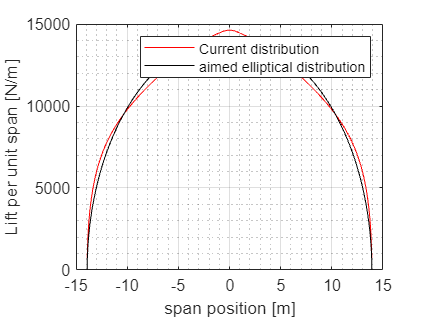

plot(semispan*cos(thetadist),Lift_plot,'r')
hold on
plot(-semispan*cos(thetadist),Lift_plot,'r')

plot(-semispan*cos(thetadist),Lift_ellipse_plot,'k')
plot(semispan*cos(thetadist),Lift_ellipse_plot,'k')



grid on
grid minor
xlabel('span position [m]')
ylabel('Lift per unit span [N/m]')
legend('Current distribution','','aimed elliptical distribution')

hold off

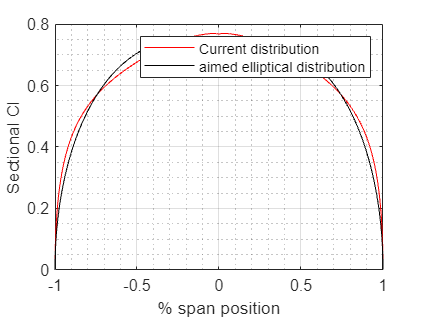


plot(1*cos(thetadist),Cl_plot,'r')
hold on
plot(-1*cos(thetadist),Cl_plot,'r')

plot(-1*cos(thetadist),Cl_ellipse_plot,'k')
plot(1*cos(thetadist),Cl_ellipse_plot,'k')
grid on
grid minor

% ylim([0 0.7])
hold off
xlabel('% span position')
ylabel('Sectional Cl')
legend('Current distribution','','aimed elliptical distribution')

## Plotting the planform

MACind = find(c_y == MACpos)

MACind = 696

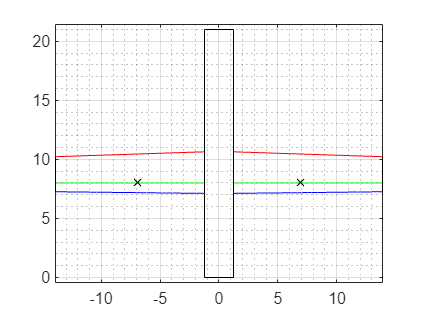

longitudinalMACac =  8;
fuselagedatum = 0;
feselageend = 21;


% plot(span_disc,c_y,'.')
% x_engine = quarterchord(ceil(length(c_y)*0.37))
% height_engine0.37*max(span_disc)*tand(5)-0.175*c_y(ceil(length(c_y)*0.37))-0.9
LEsweep = (quarterchord-quarterchord(MACind) + longitudinalMACac) - 0.25 .* c_y;
TEsweep = (quarterchord-quarterchord(MACind) + longitudinalMACac) + 0.75 .* c_y;
quarterchordplot = (quarterchord-quarterchord(MACind) + longitudinalMACac);
%origin at quarterchord point of root chord
plot (span_disc(floor(fuselage_rad*1/discret):end),LEsweep(floor(fuselage_rad*1/discret):end),'b')
hold on
plot (span_disc(floor(fuselage_rad*1/discret):end),TEsweep(floor(fuselage_rad*1/discret):end),'r')
plot (span_disc(floor(fuselage_rad*1/discret):end),quarterchordplot(floor(fuselage_rad*1/discret):end),'g')
plot (span_disc(MACind),quarterchordplot(MACind),'xk')

plot (-span_disc(floor(fuselage_rad*1/discret):end),TEsweep(floor(fuselage_rad*1/discret):end),'r')
hold on
plot (-span_disc(floor(fuselage_rad*1/discret):end),LEsweep(floor(fuselage_rad*1/discret):end),'b')
plot (-span_disc(floor(fuselage_rad*1/discret):end),quarterchordplot(floor(fuselage_rad*1/discret):end),'g')
plot (-span_disc(MACind),quarterchordplot(MACind),'xk')

plot ([span_disc(floor(fuselage_rad*1/discret)),span_disc(floor(fuselage_rad*1/discret))], [LEsweep(floor(fuselage_rad*1/discret)),TEsweep(floor(fuselage_rad*1/discret))],'k')
plot ([span_disc(end),span_disc(end)], [LEsweep(end),TEsweep(end)],'k')
plot ([-span_disc(floor(fuselage_rad*1/discret)),-span_disc(floor(fuselage_rad*1/discret))], [LEsweep(floor(fuselage_rad*1/discret)),TEsweep(floor(fuselage_rad*1/discret))],'k')
plot ([-span_disc(end),-span_disc(end)], [LEsweep(end),TEsweep(end)],'k')

plot ([span_disc(floor(fuselage_rad*1/discret)),span_disc(floor(fuselage_rad*1/discret))],[fuselagedatum,feselageend],'k')
plot ([-span_disc(floor(fuselage_rad*1/discret)),-span_disc(floor(fuselage_rad*1/discret))],[fuselagedatum,feselageend],'k')
plot ([-span_disc(floor(fuselage_rad*1/discret)),span_disc(floor(fuselage_rad*1/discret))],[fuselagedatum,fuselagedatum],'k')
plot ([-span_disc(floor(fuselage_rad*1/discret)),span_disc(floor(fuselage_rad*1/discret))],[feselageend,feselageend],'k')


axis equal
hold off
grid on
grid minor

chordpos = 0;

Cl_alpha = 6.68

Cl_alpha = 6.6800

Mach = 0.45

Mach = 0.4500

S_rat = (Sref-2*fuselage_rad*c_y(fuselage_rad*100))/Sref

S_rat = 0.9033

FLF = 1.07*(1+(2*fuselage_rad/(semispan*2)))^2

FLF = 1.2710

yetaest = 0;
CL_alpha_curve = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)

CL_alpha_curve = 5.9868


V_stall = sqrt(WS*2/(rho*2.7))

V_stall = 67.0534

function [Sref, c_y,span_disc,quarterchord,MACpos,c_bar,span] = planformcalc(AR, Sweep, Taper, Sref, discret)
%(AR, Sweep, Taper, c_bar) 
span = sqrt(AR * Sref);
c_bar = Sref/span;
span_disc = [0:discret:span/2];
syms croot;
eqn = (croot+Taper*croot)*(span/2) == Sref;
croot = double(solve(eqn,croot));
c_y =  (Taper-1)*croot/(span/2).*span_disc + croot;
MACposind = find(abs(c_y-c_bar) == min(abs(c_y-c_bar)));
MACpos = c_y(MACposind);
quarterchord =  span_disc .* tand(Sweep);


% s_1 = 0.25 * AR * (1+Taper); %_1 using 1 as reference root chord length
% Sref_1 = (1 + Taper) * s_1;
% span_disc_1 = [0:0.01:s_1];
% c_y_1 = 1 - ((1-Taper)/s_1) * span_disc_1;
% c_bar_1 = 2*trapz(span_disc_1,(c_y_1).^2)/Sref_1;
% ratio = c_bar/c_bar_1; % dimensionalize using c_bar, can be changed later to root or tip chord length
% s = ratio*s_1;
% Sref = ratio * (1 + Taper) * s;
% span_disc = [0:0.01:s];
% c_y =  (1 - ((1-Taper)/s) * span_disc)*ratio;
% temp1 = (c_y - c_bar).^2;
% MACpos = find(temp1 == min(temp1));
% quarterchord =  span_disc .* tand(Sweep);
end
function [CL_alpha_curve] = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)
beta = (1-Mach^2)^0.5;
if yetaest == 0
    yeta = Cl_alpha/(2*pi/beta);
else
    yeta = yetaest;
end
CL_alpha_curve = 2*pi*AR/(2+(4+((AR^2*beta^2)/(yeta^2))*(1+(tand(Sweep))^2/(beta^2)))^0.5) * S_rat * FLF;
end